clc; clear; clear('global'); close all;

## FRUCD Tire Model Fitting Tool Main Script

This script fits a Pacejka contact patch tire model and radial deflection models to Calspan TTC Data Sets and creates an instance of the FRUCDTire class for use in vehicle models.

Use MATLAB, SI Unit Calspan TTC Data Sets

Authors: 

- Blake Christierson (Sep. 2018 - Jun. 2021) 

- Carlos Lopez         (Jan. 2019 - ??? )

## Initialization

% Global Variables
global Directory Figure
% Figure Interpreter
set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultAxesTickLabelInterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');

% Default Directories
Directory.Tool = fileparts( matlab.desktop.editor.getActiveFilename );
Directory.Data = [Directory.Tool(1:max(strfind( Directory.Tool,'\' ))), 'Tire-Data'];
Directory.Save = [Directory.Tool, '\Models'];

addpath( genpath( Directory.Tool ) );
addpath( genpath( Directory.Data ) );

% Figure Structure
Figure.Mode  = 'Debug';
Figure.State = 'minimized';

% Initializing Tire Model
Tire = ModelParameterSetup;

## Data Import

%{
TestName = { 'Transient'                 , ...
             'Cornering 1'               , ...
             'Cornering 2'               , ...
             'Warmup'                    , ...
             'Drive, Brake, & Combined 1', ...
             'Drive, Brake, & Combined 2'};

% Change Current Directory to Default Data Directory
cd( Directory.Data )

% Import Run Files
for i = 1 : 6
    [FileName, PathName] = uigetfile( { '*.mat;*.dat' }, ...
         ['Please select the ', TestName{i}, ' Run Data File'] );  
    
    if ~ischar( FileName )
        continue
    else    
        Data(i) = DataImport( fullfile( PathName, FileName ), TestName{i} ); %#ok<SAGROW>
    end
end

% Empty Check
if exist( 'Data', 'var' ) == 0
    error( 'No Run Data Files Selected' );
end

clear TestName FileName PathName
%}
load('TestData_1_21_21_14_00.mat')

## Binning Run Data

for i = find( ~cellfun( @isempty, { Data(:).Source } ) )
   Bin(i) = DataBinning( Data(i) ); %#ok<SAGROW>
end

clear i

## Steady State, Pure Slip

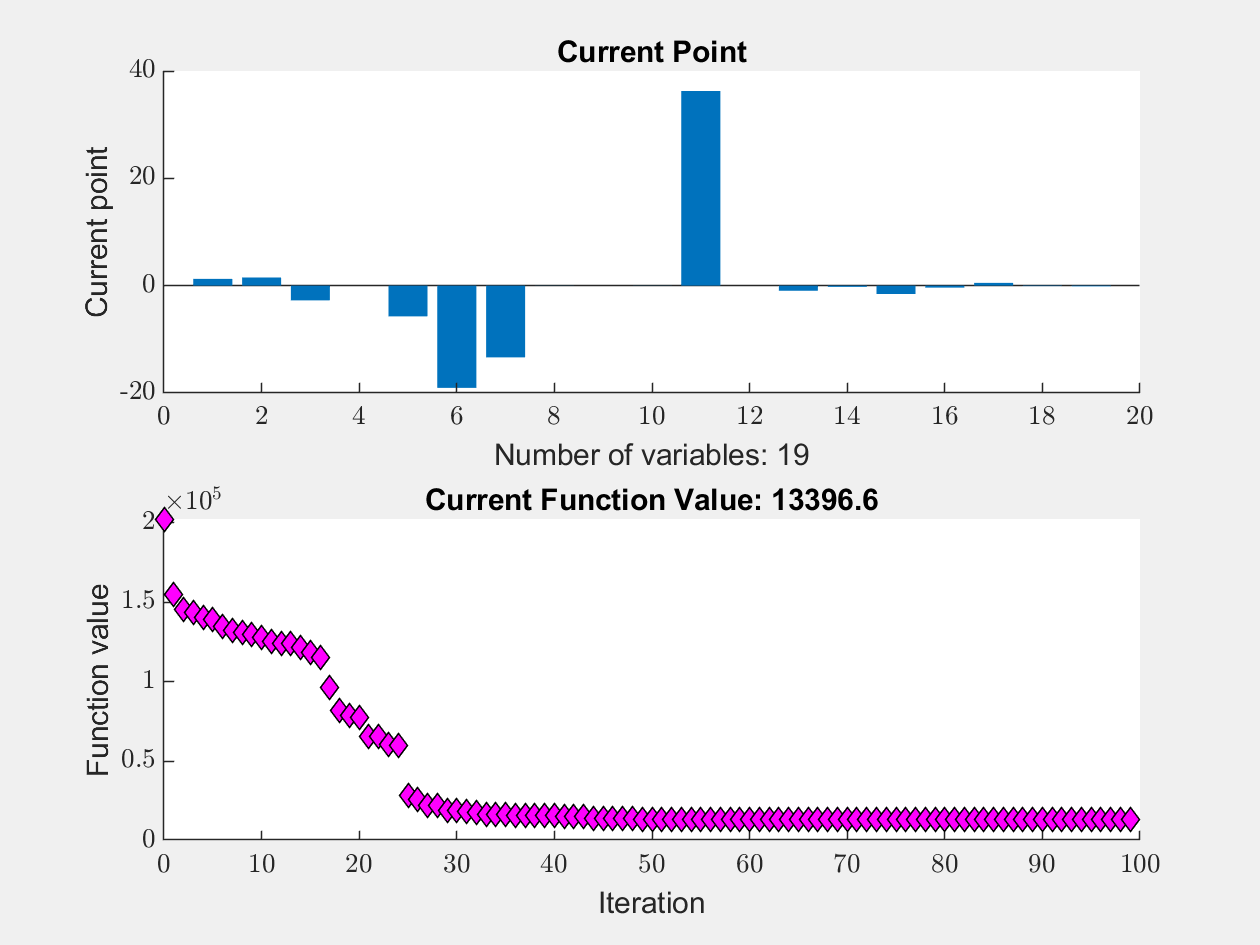

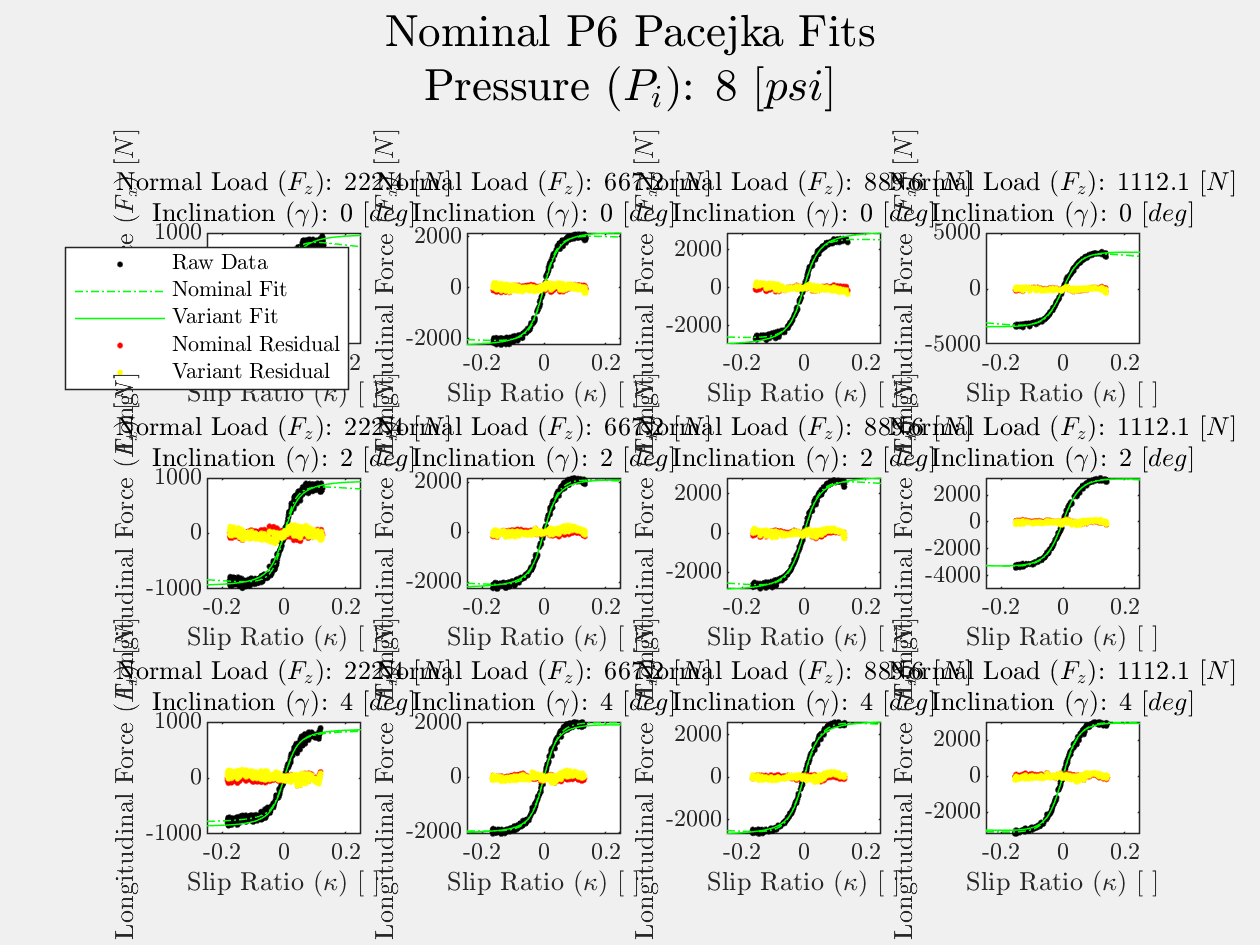

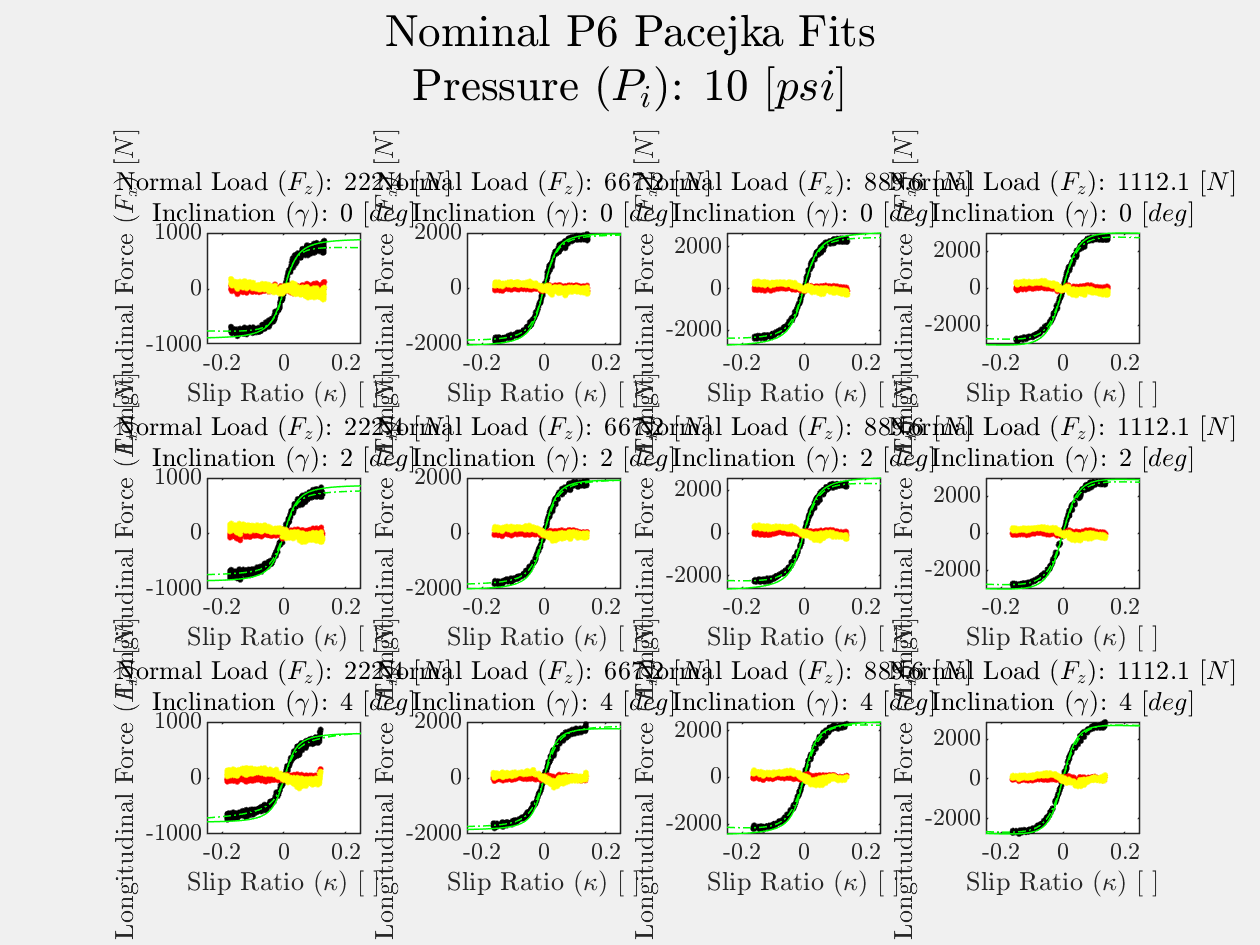

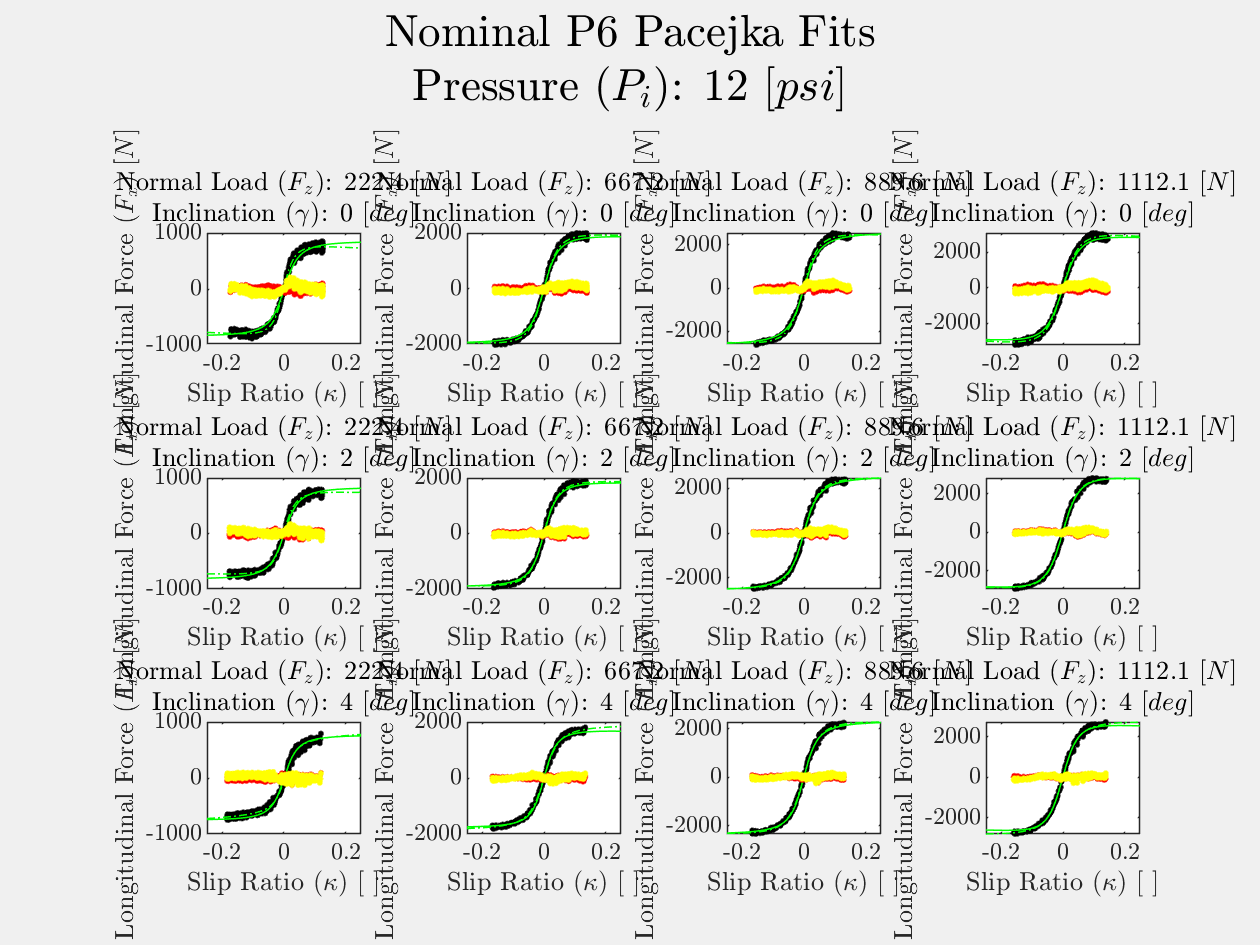

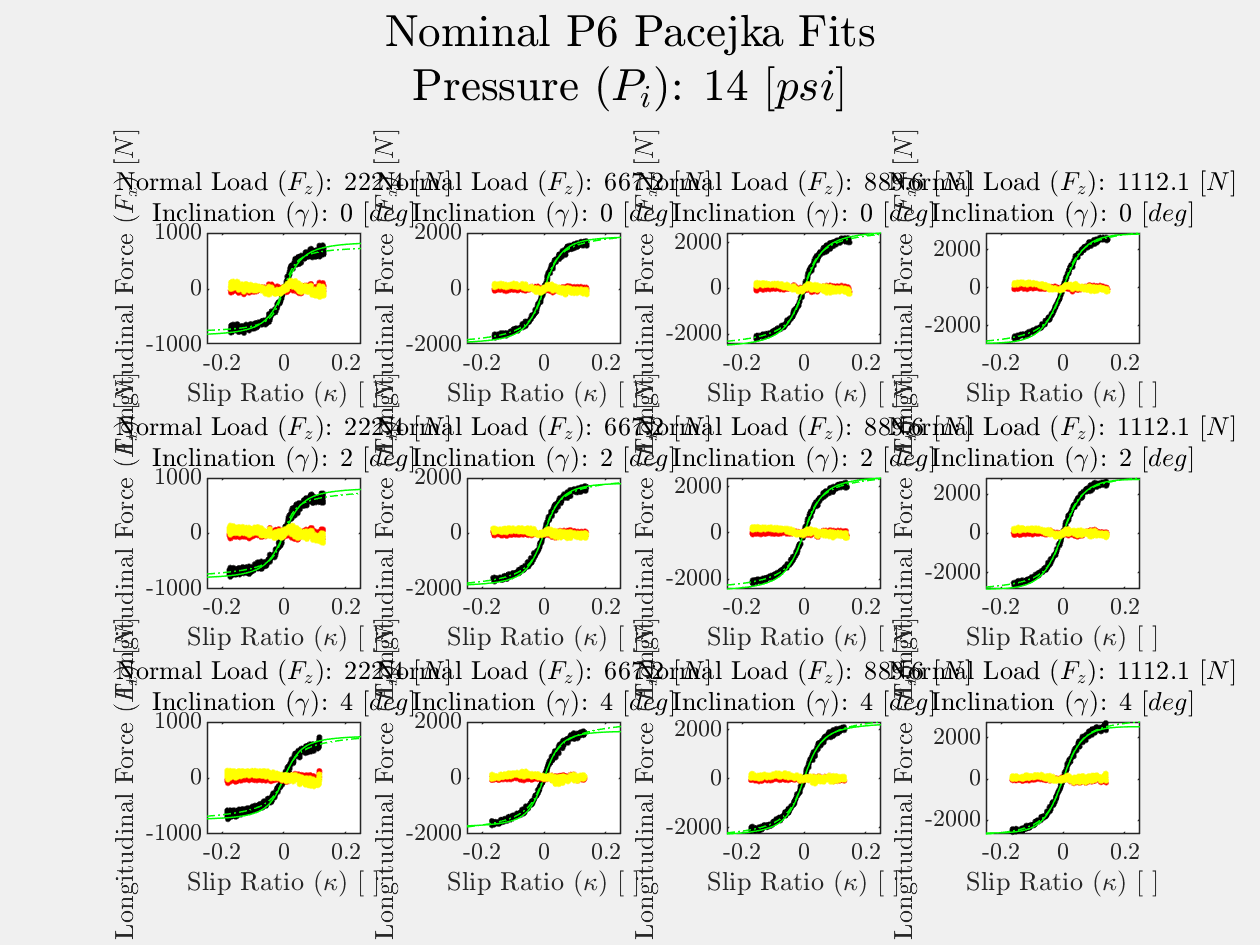

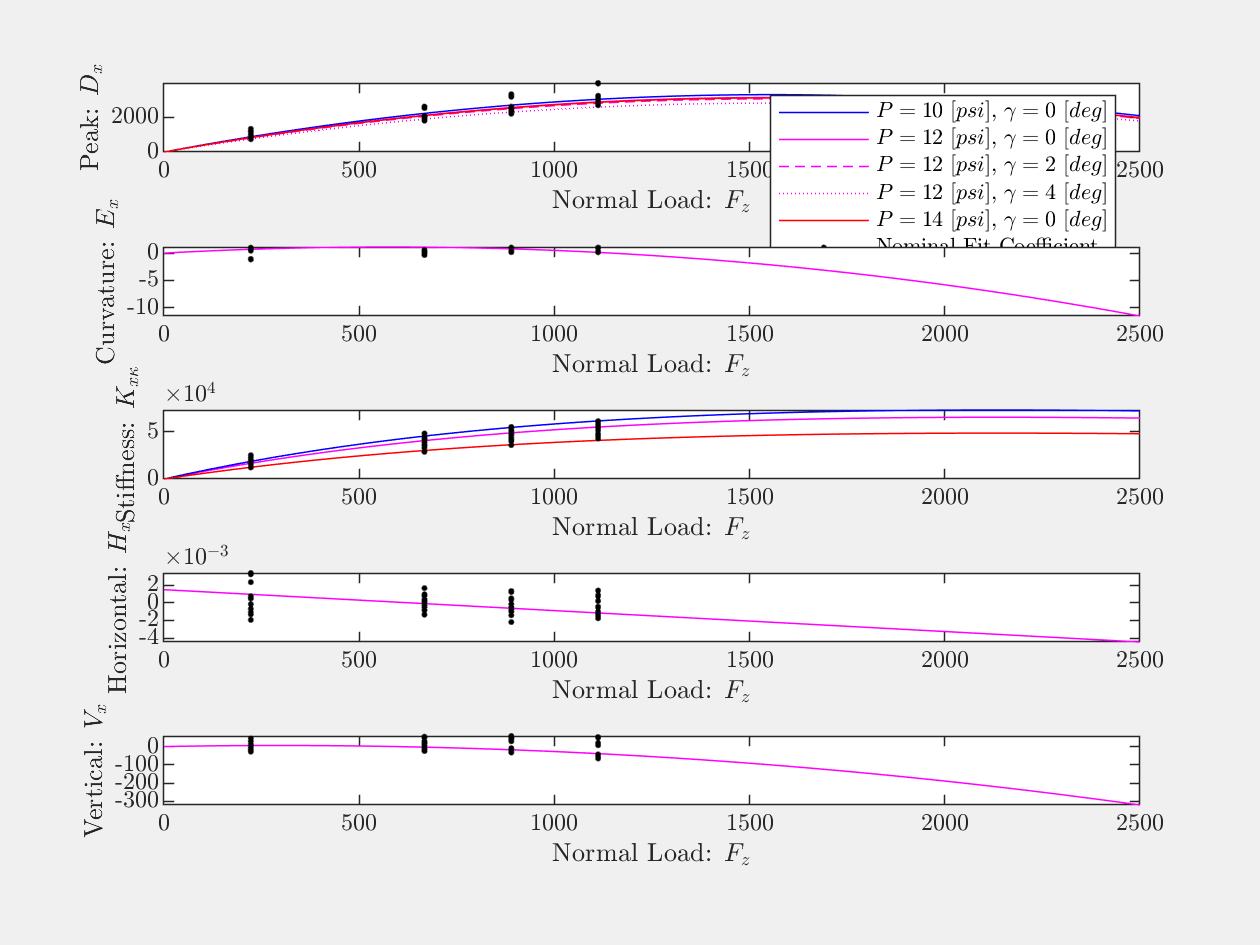

% Longitudinal Force Fitting ( Fxo )
Tire = PureLongitudinalFitting( Tire, Data, Bin );

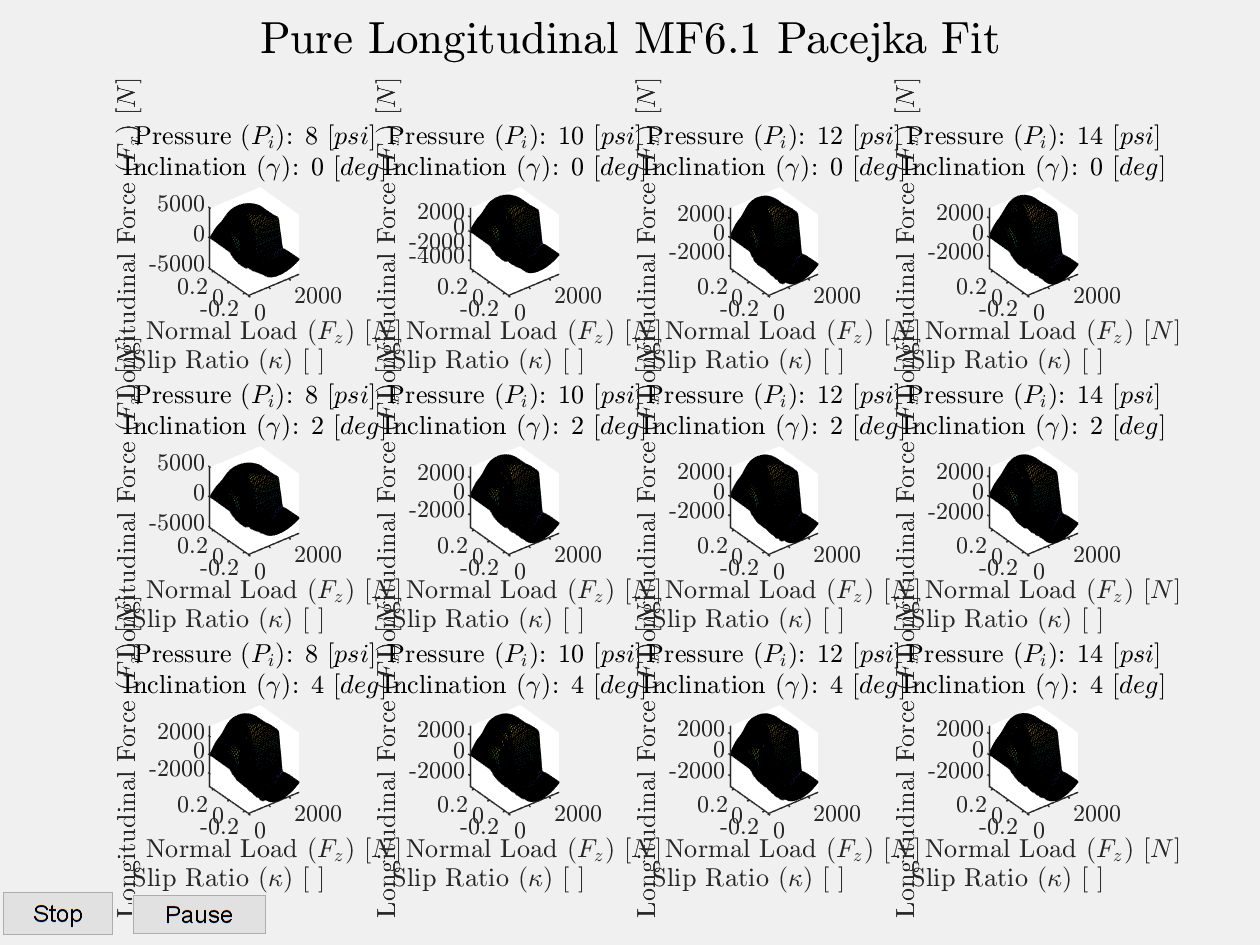

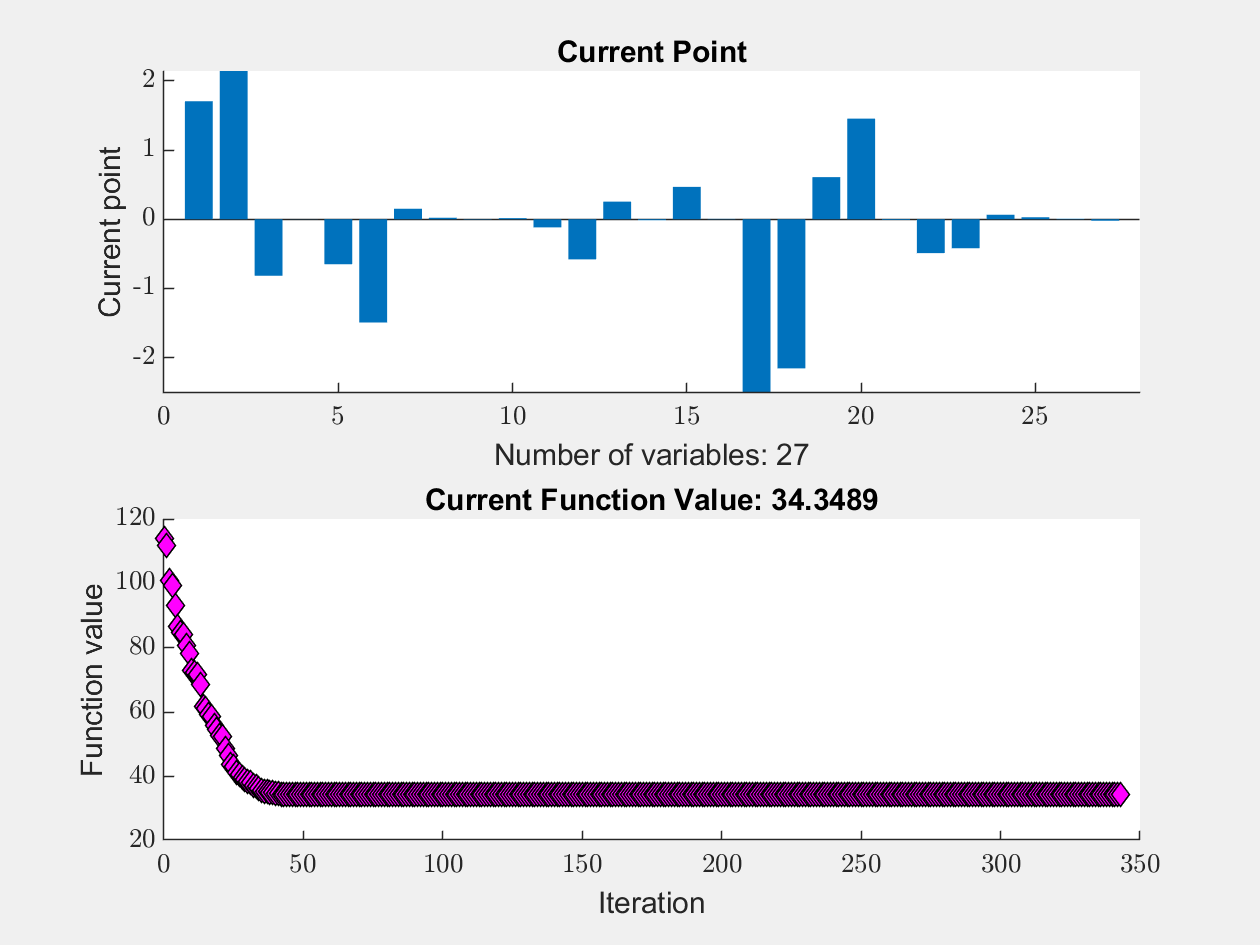

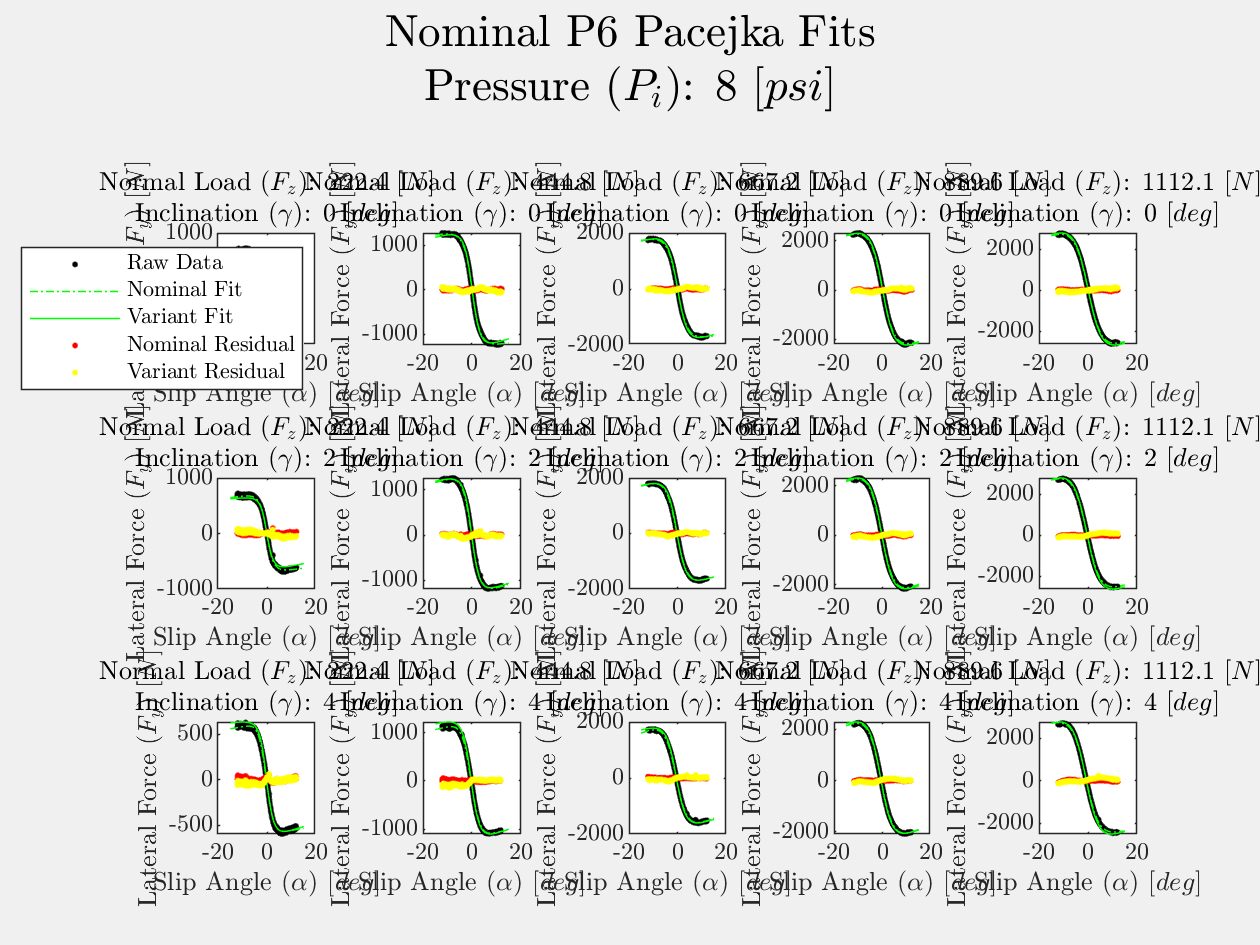

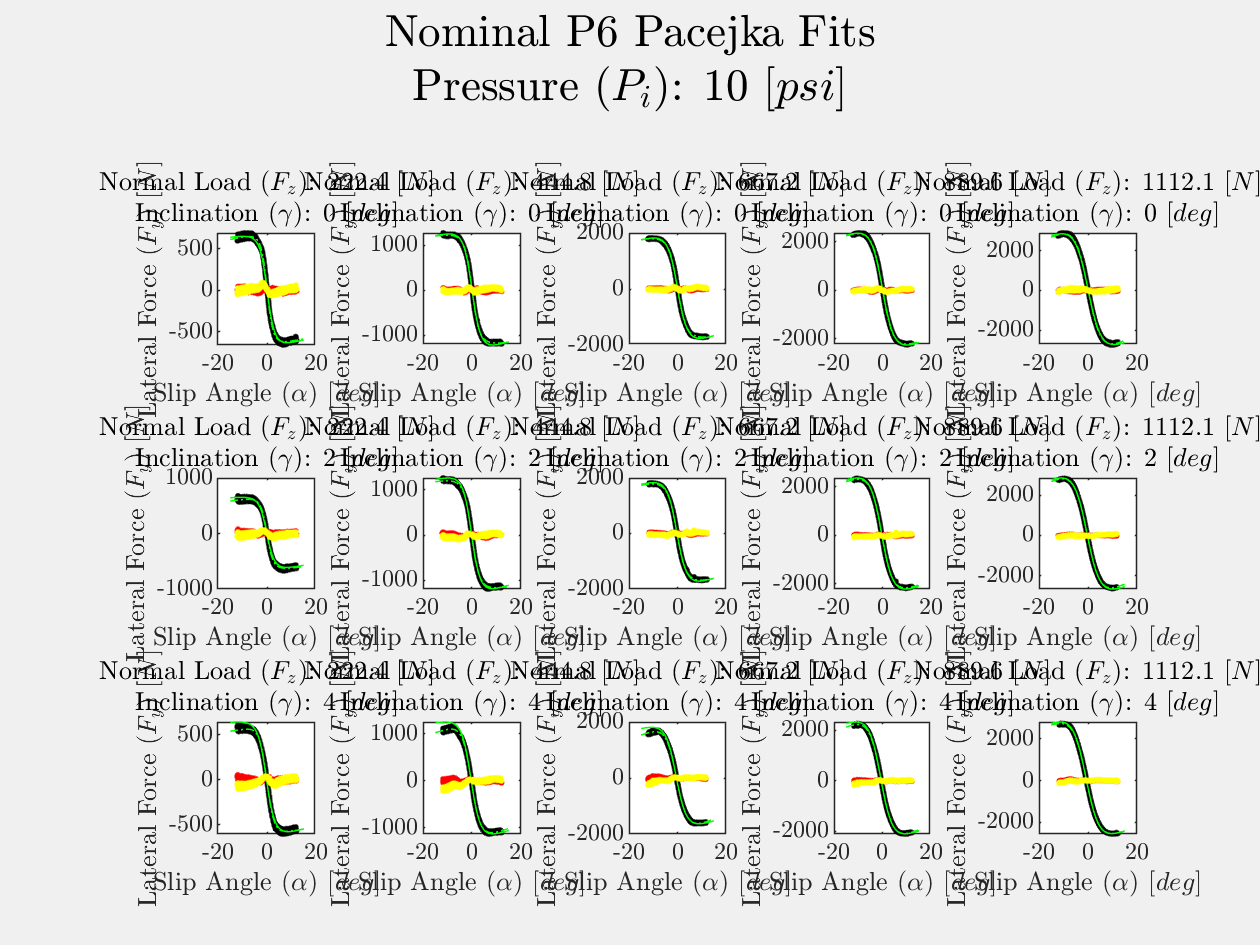

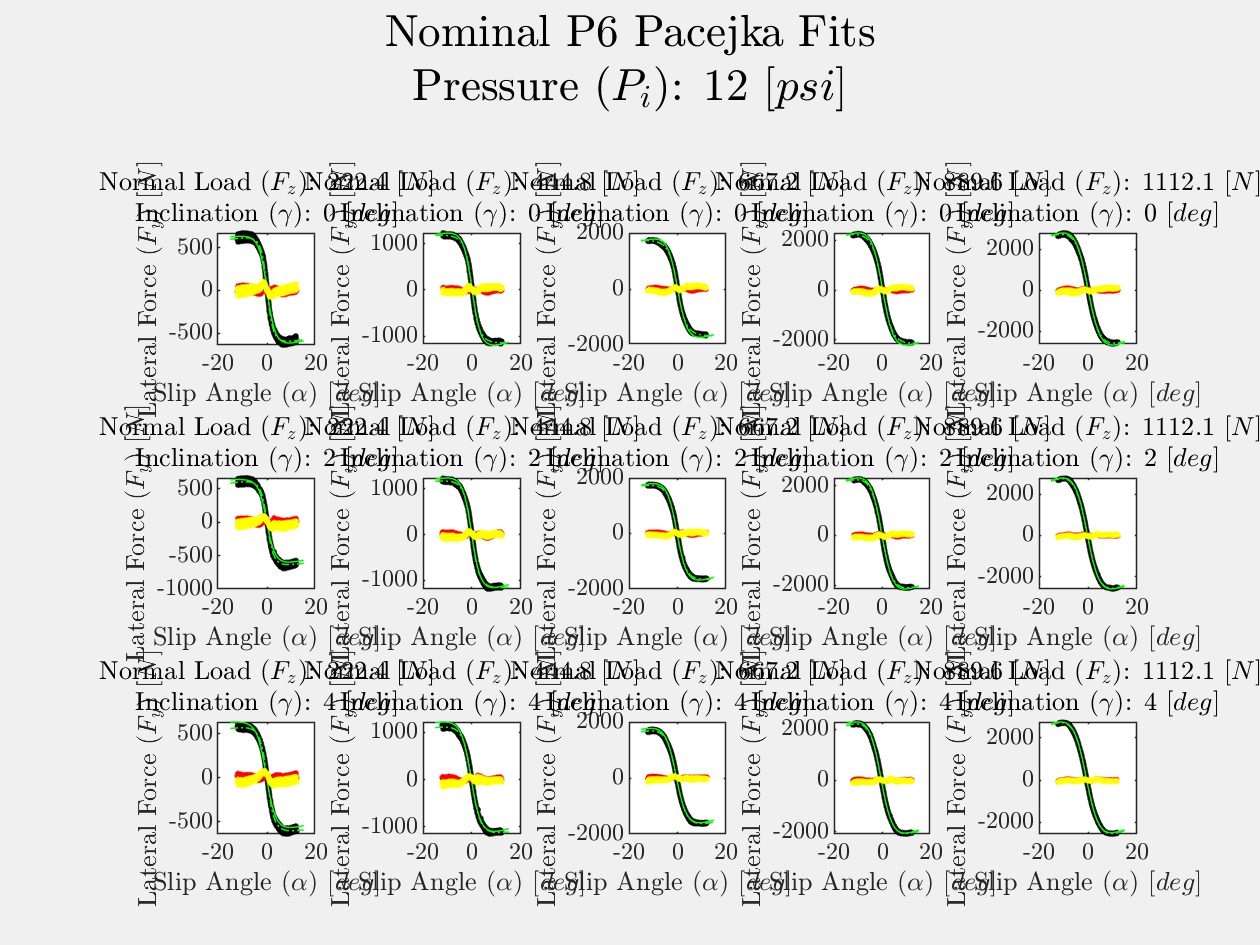

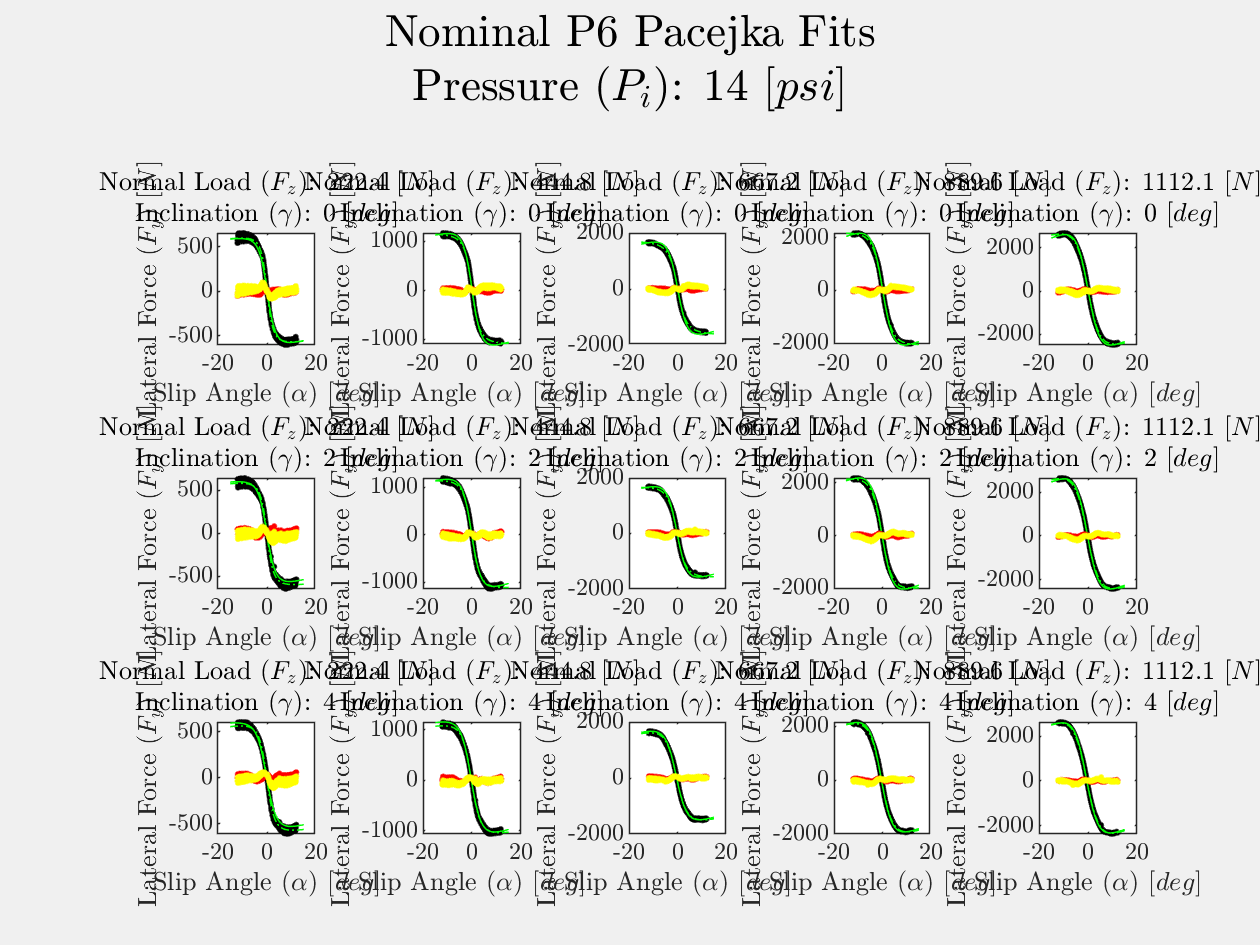

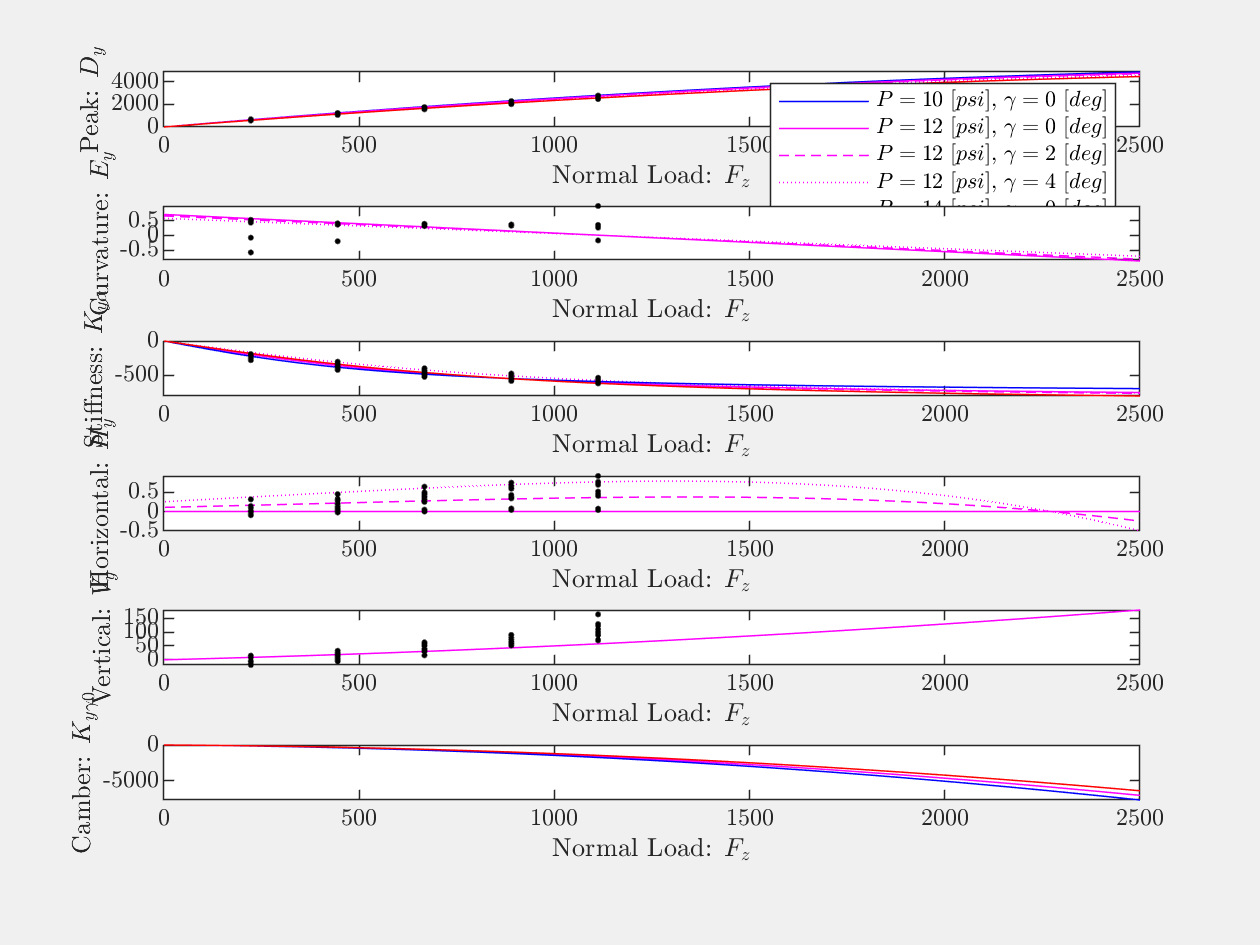

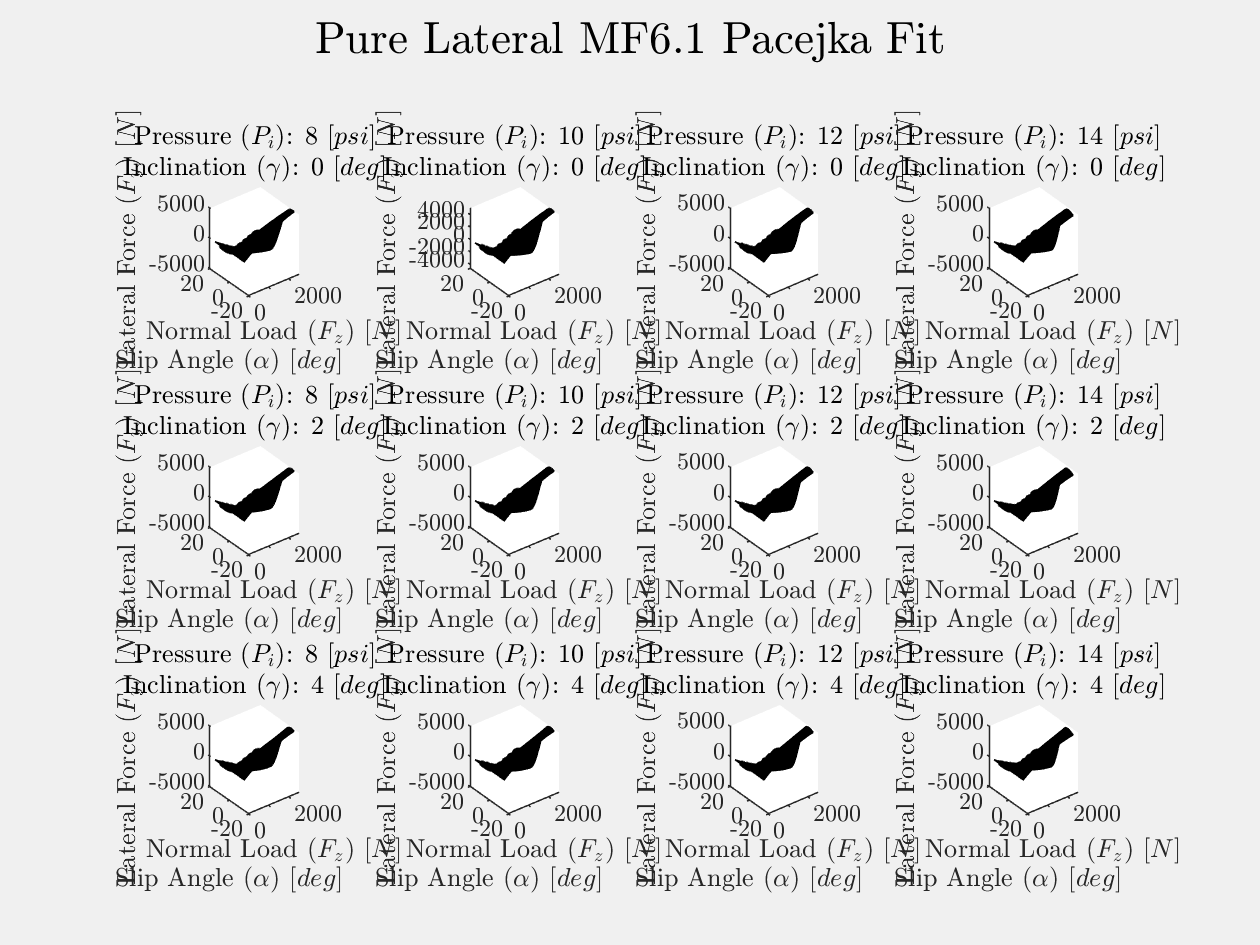


% Lateral Force Fitting ( Fyo )
Tire = PureLateralFitting( Tire, Data, Bin );


return

% Aligning Moment Fitting ( Mzo )
Tire = PureAligningFitting( Tire, Data, Bin );

## Steady State, Combined Slip

This is currently undeveloped due to data limitations. Instead, combined tire forces can be evaluated using the Modified-Nicolas-Comstock (MNC) Model to couple pure slip model. It is implemented within the FRUCDTire Class Definition.

## Transient, Pure Slip Response

## Camber Evaluation Plots

for p = 1:length(Tire.run{2}.binval.P)
    
    Fig{p}.GAM = figure('Name','Optimal Camber from Tread Temperature Differential');
    
    for c = 2:length(Tire.run{2}.binval.IA)
        if p == 1
            i = 3;
        else 
            i = 2;
        end
        
        validIdx = Tire.run{i}.bin.P(:,p) & Tire.run{i}.bin.IA(:,c);
      
        if sum(validIdx) > 25
            
            subplot(3,1,c-1)
            hold on
            
            plot(Tire.run{i}.dat.ET(validIdx),...
                Tire.run{i}.dat.TSTC(validIdx) - ...
                Tire.run{i}.dat.TSTO(validIdx),...
                Tire.run{i}.dat.ET(validIdx),...
                Tire.run{i}.dat.TSTC(validIdx) - ...
                Tire.run{i}.dat.TSTI(validIdx));
            
            title({strcat('$P = ',num2str(Tire.run{i}.binval.P(:,p)), ...
                '$, $\gamma = ',num2str(Tire.run{i}.binval.IA(:,c)), ...
                '$')}, 'Interpreter','latex')
            
            xlabel('Elapsed Time (sec)','Interpreter','latex')
            ylabel('Temperature Differential ($^{\circ}$C)','Interpreter','latex')
            set(gca,'TickLabelInterpreter','latex')
            
            legend({'Outer Temperature Differential', ...
                'Inner Temperature Differential'},'Interpreter','latex')
            
            ylim([-15 15])
        end
    end
end

## Radial Deflection Modeling

Cornering Stiffness Modeling

for p = 2
    if p == 1
        i = 3;
    else
        i = 2;
    end
    
    [Tire.RL{1},Tire.RL{2}] = LR_P6( ...
        (16/2)*2.54 - ...
        Tire.run{i}.dat.RL(Tire.run{i}.bin.P(:,p)), ...
        abs(Tire.run{i}.dat.FZ(Tire.run{i}.bin.P(:,p))));
end

## Transient Tire Dynamics

Tire = TransientRelaxationLength( Tire, Data, Bin );